# `Creación del primer modelo de la red neuronal CNN 3`

`Este modelo consiste en una red convolución que se toma de referencia de la propiuesta en el link de MATLAB, esta red no posee capa de maxpooling, únicamente las capas convolucionales con la función de activación ReLU. El tamaño del filtro es de 3x3, lo cual permite un menor número de parámetros entrenables comparado con el primer modelo desarrollado y redes más profundas (más capas pero menos densidad), así mismo, se emplea un padding de same y capas de maxpooling, lo cual ayuda a mantener el tamaño de la entrada y extraer las características más importantes de la cuadrícula de recursos.`

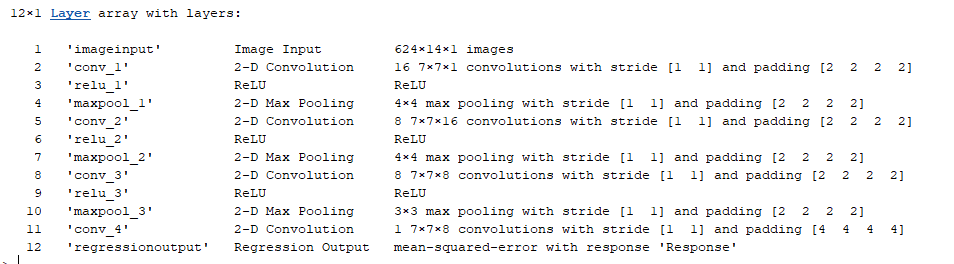

`El archivo del modelo 3_1 corresponde a `

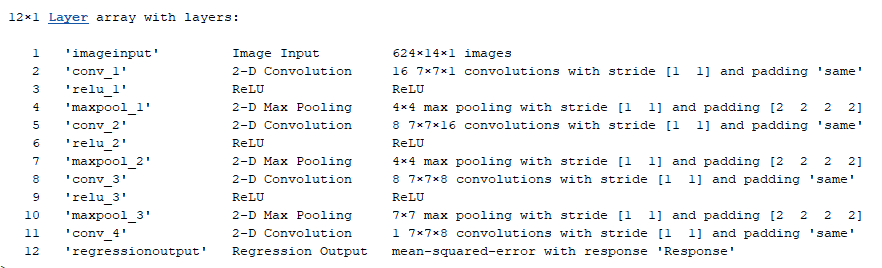

`El archivo del modelo 3_2 es: `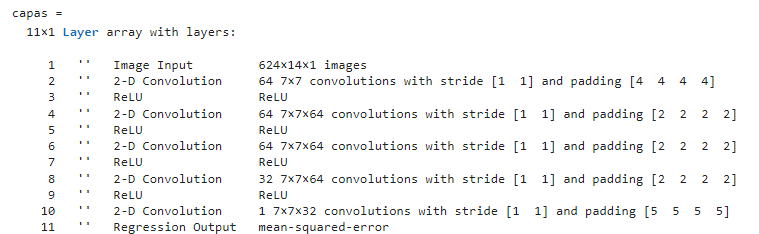

clc; clear all;

enable_Train = false;
data = load("X_train.mat");
label = load("Y_train.mat");

%Se importan los datos y las variables asociadas con los datos para el
%entrenamiento
data = data.x_train;
label = label.y_train;

size(label)

ans =    624.0000e+000    14.0000e+000     2.0000e+000     1.0000e+003


[subport, simbolos, valor] = size(label)

subport =    624.0000e+000

simbolos =     14.0000e+000

valor =      2.0000e+003

ratio = 0.75; %Porcentaje para la separación de los datos

[trainId,~,testId] = dividerand(1000,ratio,0.0,1-ratio);

x_train = data(:,:,:,trainId);
y_train = label(:,:,:,trainId);

x_val = data(:,:,:,testId);
y_val = label(:,:,:,testId);


[Python_list,datos_py] = pyrunfile("CNN_Channel.py",["rxGrid","datos"],Activacion="True",X_train=x_train);

Hola matlab


Python_list = double(Python_list);
datos_py = double (datos_py);


x_train = cat(4, x_train(:,:,1,:), x_train(:,:,2,:));
y_train = cat(4, y_train(:,:,1,:), y_train(:,:,2,:));

x_test = cat(4, x_val(:,:,1,:), x_val(:,:,2,:));
y_test = cat(4, y_val(:,:,1,:), y_val(:,:,2,:));

rng(42);

if enable_Train
    batch = 32; % Es el número de ejemplos que se introducen en la red.
    
    %Esta variable se usa para verificar 5 veces en cada época.
    valFrequency = round(size(x_train,4)/batch/5); 


    %Aquí se puede definir las capas que van a componer la RNA

    % capas = [
    %     imageInputLayer([subport simbolos 1],'Normalization','none')
    %     convolution2dLayer(7,16,'Padding','same')
    %     reluLayer
    %     maxPooling2dLayer(4,"Padding",2)
    %     convolution2dLayer(7,8,'Padding','same')
    %     reluLayer
    %     maxPooling2dLayer(4,"Padding",2)
    %     convolution2dLayer(7,8,'Padding','same')
    %     reluLayer
    %     maxPooling2dLayer(7,"Padding",2)
    %     convolution2dLayer(7,1,'Padding','same')
    %     regressionLayer
    % ]

    capas = [
        imageInputLayer([subport simbolos 1],'Normalization','none')
        convolution2dLayer(7,64,'Padding',4)
        reluLayer
        convolution2dLayer(7,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(7,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(7,32,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(7,1,'Padding',5,'NumChannels',32)
        regressionLayer
    ]


    hiper_param = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',5, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batch, ...
        'ValidationData',{x_test, y_test}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);


    [estimacionRNA, infoRNA] = trainNetwork(x_train, ...
        y_train,capas,hiper_param);

    save('Modelo3_2.mat', "estimacionRNA");

else
    load("CNN_Modelo3.mat");
end


load('CNN_Modelo3.mat')